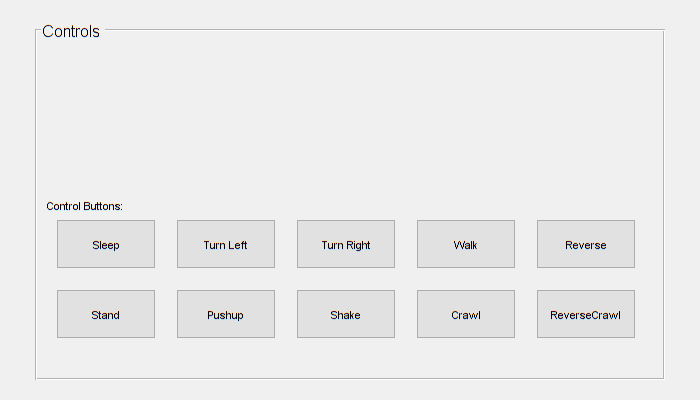

f = figure('Name', 'Robot Control', 'NumberTitle', 'off');
f.Position(3) = 700; % Set the figure width
f.Position(4) = 400; % Set the figure height

panel = uipanel(f, 'Title', 'Controls', 'FontSize', 12, 'Position', [.05 .05 .9 .9]);

valueLabel3 = uicontrol(panel, 'Style', 'text', 'Position', [0 160 100 20], 'HorizontalAlignment', 'center', 'String', 'Control Buttons:');

btn1 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Sleep', 'Position', [20 110 100 50], 'Callback', {@store_callback, f});
btn2 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Turn Left', 'Position', [140 110 100 50], 'Callback', {@left_callback, f});
btn3 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Turn Right', 'Position', [260 110 100 50], 'Callback', {@right_callback, f});
btn4 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Walk', 'Position', [380 110 100 50], 'Callback', {@walk_callback, f});
btn5 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Reverse', 'Position', [500 110 100 50], 'Callback', {@reverse_callback, f});
btn6 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Stand', 'Position', [20 40 100 50], 'Callback', {@stand_callback, f});
btn7 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Pushup', 'Position', [140 40 100 50], 'Callback', {@pushup_callback, f});
btn8 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Shake', 'Position', [260 40 100 50], 'Callback', {@shake_callback, f});
btn9 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'Crawl', 'Position', [380 40 100 50], 'Callback', {@crawl_callback, f});
btn10 = uicontrol(panel, 'Style', 'pushbutton', 'String', 'ReverseCrawl', 'Position', [500 40 100 50], 'Callback', {@reverse_crawl_callback, f});


s = serialport('COM6', 9600);
f.UserData = s;


function store_callback(src, event, f)
    s = f.UserData;
    fprintf('Store button pressed.\n');
    write(s, 's', "char");
end

function right_callback(src, event, f)
    s = f.UserData;
    fprintf('Right button pressed.\n');
    write(s, 'r', "char");
end

function left_callback(src, event, f)
    s = f.UserData;
    fprintf('Left button pressed.\n');
    write(s, 'l', "char");
end

function walk_callback(src, event, f)
    s = f.UserData;
    fprintf('Walk button pressed.\n');
    write(s, 'w', "char");
end

function reverse_callback(src, event, f)
    s = f.UserData;
    fprintf('Reverse button pressed.\n');
    write(s, 'u', "char");
end

function stand_callback(src, event, f)
    s = f.UserData;
    fprintf('Stand button pressed.\n');
    write(s, 't', "char");
end

function pushup_callback(src, event, f)
    s = f.UserData;
    fprintf('Pushup button pressed.\n');
    write(s, 'p', "char");
end

function shake_callback(src, event, f)
    s = f.UserData;
    fprintf('Shake button pressed.\n');
    write(s, 'h', "char");
end

function crawl_callback(src, event, f)
    s = f.UserData;
    fprintf('Crawl button pressed.\n');
    write(s, 'c', "char");
end

function reverse_crawl_callback(src, event, f)
    s = f.UserData;
    fprintf('ReverseCrawl button pressed.\n');
    write(s, 'v', "char");
end
